# getGift Bow

Tis the season for a MATLAB holiday algorithm!

Use the embedded controls to modify parameters for the bow, and create your own.

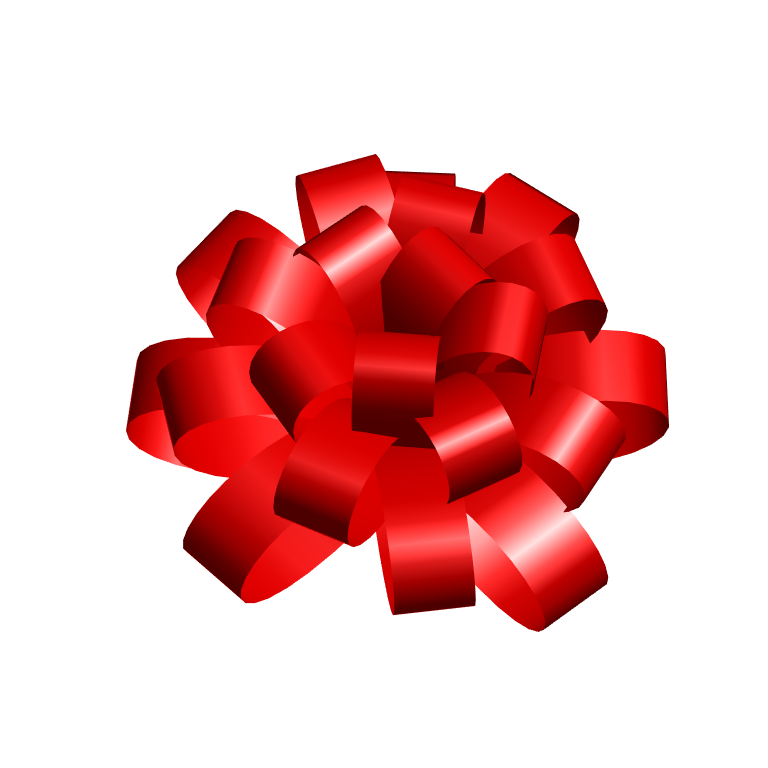

nloops = 21; % Number of loops in the bow
lwphi = 0.2; % Loop width across phi normalized radians
height = 1; % Height of the bow
ribbonwidth = 0.3; % Width of ribbon
color = [1 0 0]; % Color of the ribbon

npts = 21; % Number of vertices in a loop (should be odd)

% Create geometry for each loop as a line in spherical coordinates
% and then convert to cartesian.
[X,Y,Z] = sph2cart(...
    repmat((1+sqrt(5))*(1:nloops),npts,1)*pi,...
    (linspace(.5,1,nloops).^.8+linspace(-lwphi,lwphi,npts)'.*linspace(.8,1,nloops))*pi,...
    ones(1,nloops).*(1-abs(linspace(-1,1,npts)'.^2)));

% Use streamribbon to create the bow's ribbon.
% streamribbon needs the columns of our vertices, and of the twist
% angle to be provided as a cell array of matrices.
streamverts = mat2cell([ reshape(X,[],1) reshape(Y,[],1) reshape(Z,[],1)*height ],repelem(npts,nloops))';
twistangle = mat2cell(repmat([pi/2;zeros(npts-1,1)],nloops,1), repelem(npts,nloops))';

% Display our fancy gift bow
clf
set(gcf,'position',[10 10 512 512])
srf=streamribbon(streamverts,twistangle,ribbonwidth);
view([0 60]);
set(srf,'FaceColor',color,'EdgeColor','none','FaceLighting','gouraud');
axis off tight equal
camlight